clc;clear
aFilt = weightingFilter('A-weighting', 441000)

aFilt =   weightingFilter with properties:

        Method: 'A-weighting'
    SampleRate: 441000


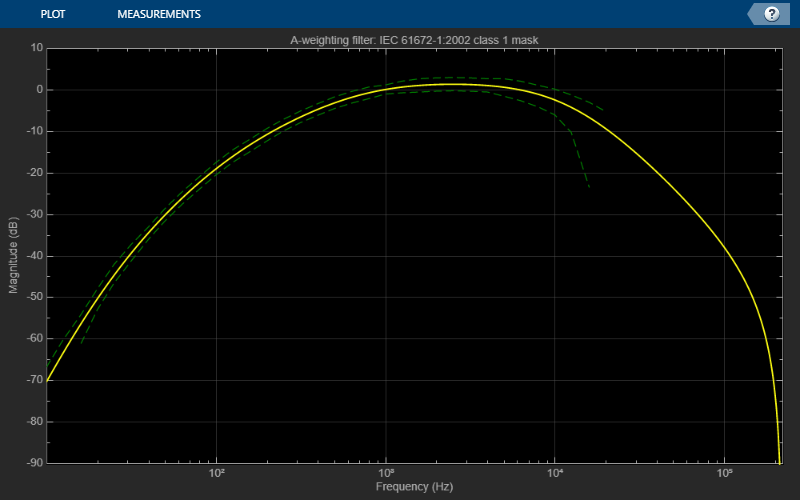

visualize(aFilt,'class 1');


sos = getFilter(aFilt)

sos =   dsp.SOSFilter with properties:

            Structure: 'Direct form II transposed'
    CoefficientSource: 'Property'
            Numerator: [3×3 double]
          Denominator: [3×3 double]
       HasScaleValues: true
          ScaleValues: [4×1 double]

  Show all properties


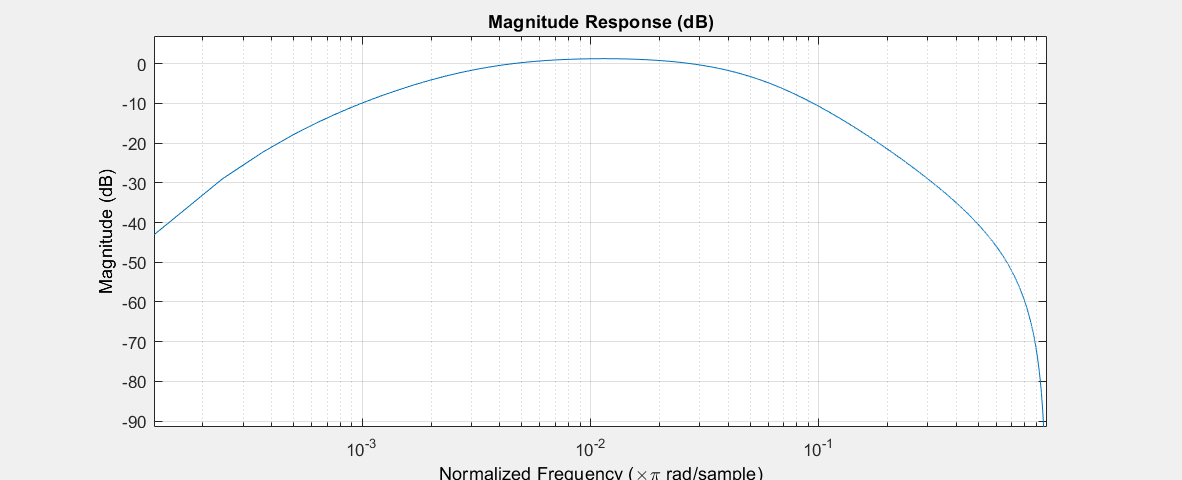

fvtool(sos,'FrequencyScale','log')

sos.info

ans = 6×70 char array
    'Discrete-Time IIR Filter (real)                                       '
    '-------------------------------                                       '
    'Filter Structure    : Direct-Form II Transposed, Second-Order Sections'
    'Number of Sections  : 3                                               '
    'Stable              : Yes                                             '
    'Linear Phase        : No                                              '


coeffsSOS = sos.coeffs

coeffsSOS = struct with fields:
      SOSMatrix: [3×6 double]
    ScaleValues: [4×1 double]



% To use the coefficients with an ARM device, the fourth column is removed (all 1's by design), 
% the last two columns undergo a sign reversal, and the matrix is flattened.
coeffs = reshape(coeffsSOS.SOSMatrix(:,[1 2 3 5 6])' .* [1 1 1 -1 -1]',[],1);

% create string for copy/paste, cut off last ,\n
coeffStr = sprintf('%1.10ff,\n',coeffs);
disp(coeffStr(1:end-2));

1.0000000000f,
2.0000000000f,
1.0000000000f,
1.6802960799f,
-0.7058487290f,
1.0000000000f,
-2.0000000000f,
1.0000000000f,
1.9880095997f,
-0.9880256274f,
1.0000000000f,
-2.0000000000f,
1.0000000000f,
1.9994131142f,
-0.9994132003f



scaleStr = sprintf('%1.10ff,\n',coeffsSOS.ScaleValues);
disp(scaleStr(1:end-2));

0.0079873655f,
1.0000000000f,
1.0000000000f,
1.0000000000f
